# Actividad Práctica N°2: Diseño de controladores en variables de estado en tiempo continuo

## Caso de estudio 2. Sistema no lineal de cuatro variables de estado

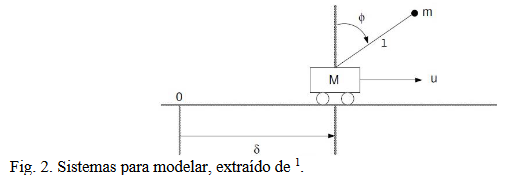

Para el caso del esquema del péndulo invertido de la figura 2, donde el modelo es:


$$\left\lbrace \begin{array}{ll}
\left(M+m\right)\ddot{\delta +\textrm{ml}\ddot{\phi \;} \cos \left(\phi \;\right)-\textrm{ml}\dot{\phi {\;}^2 \textrm{sen}\left(\phi \right)+F\dot{\;\delta \;} =u} }  & \;\\
l\ddot{\phi \;} -\textrm{gsen}\left(\phi \;\right)+\ddot{\delta \;} \cos \left(\delta \;\right)=0 & \;
\end{array}\right.$$


Con las variables de estado $x={\left\lbrack \delta \;\;\dot{\;\delta \;} \;\;\phi \;\;\;\dot{\;\phi \;} \right\rbrack }^T$, y los valores de los coeficientes:

- 
$$m=0\ldotp 1$$


- 
$$F=0\ldotp 1$$


- 
$$l=1$$


- 
$$g=9\ldotp 8$$


- 
$$M=1\ldotp 5$$


Determinar $\Delta \;t$ y el tiempo de simulación adecuados.

- Calcular un controlador que haga evolucionar al péndulo en el equilibrio inestable, partiendo de una condición inicial nula en el desplazamiento y termine en -10 metros manteniendo la vertical. Determinar el ángulo máximo que puede alejarse de la vertical en t=0 para que el sistema cumpla el objetivo de control.

- Incorporar un observador para el caso en que sólo puedan medirse el desplazamiento $\delta \;$ y el ángulo $\phi \;$, repetir las simulaciones para las condiciones anteriores y graficar los resultados en gráficas superpuestas.

- Calcular un controlador que haga evolucionar al péndulo en el equilibrio estable, partiendo de una condición inicial nula en el desplazamiento y el ángulo en $\pi \;$ que termine en 2 metros evitando las oscilaciones de la masa m, considerando que es una grúa. Una vez que $\delta =2$ modificar a m a un valor 10 veces mayor y volver al origen evitando oscilaciones.

- Incorporar un observador para el caso en que sólo pueden medirse el desplazamiento $\delta \;$ y el ángulo $\phi \;$, repetir las simulaciones para las condiciones anteriores y graficar los resultados en gráficas superpuestas para el equilibrio estable.

### Resolución del problema linealizado:

Primero se definen las constantes:

m = 0.1;
F = 0.1;
l = 1;
g = 9.8;
M = 1.5;

Ahora, las matrices:

A = [0 1 0 0; 0 -F/M -m*g/M 0; 0 0 0 1; 0 F/(l*M) g*(M+m)/(l*M) 0]

A =          0    1.0000         0         0
         0   -0.0667   -0.6533         0
         0         0         0    1.0000
         0    0.0667   10.4533         0


B = [0; 1/M; 0; -1/(l*M)]

B =          0
    0.6667
         0
   -0.6667


C = [1 0 0 0; 0 0 1 0]

C =      1     0     0     0
     0     0     1     0


D = [0 0]'

D =      0
     0


Se declaran estados, entradas y salidas, de modo de usar la función ss().

states = {'delta','deltaP','phi','phiP'};
inputs = {'u'};
outputs = {'delta','phi'};

Se crea entonces el modelo en espacio de estados:

olSystem = ss(A,B,C,D,'Statename',states,'Inputname',inputs,'Outputname',outputs);

Se puede hablar de la siguiente función de transferencia en forma matricial:

tf(olSystem)

ans =
 
  From input "u" to output...
               0.6667 s^2 + 5.921e-16 s - 6.533
   delta:  ----------------------------------------
           s^4 + 0.06667 s^3 - 10.45 s^2 - 0.6533 s
 
                      -0.6667 s
   phi:  ------------------------------------
         s^3 + 0.06667 s^2 - 10.45 s - 0.6533
 
Continuous-time transfer function.
Model Properties


Los polos a lazo abierto son:

olPoles = eig(A)

olPoles =          0
   -0.0625
   -3.2353
    3.2311


La matriz de controlabilidad del sistema se obtiene a continuación:

M = ctrb(olSystem)

M =          0    0.6667   -0.0444    0.4385
    0.6667   -0.0444    0.4385   -0.0583
         0   -0.6667    0.0444   -6.9719
   -0.6667    0.0444   -6.9719    0.4938


Se crean las siguientes variables para el uso de un LQR.

Q = C'*C;
R = 1;
K = lqr(A,B,Q,R)

K =    -1.0000   -2.5147  -44.2027  -13.7997


Las nuevas matrices a implementar son:

Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [D];
states = {'delta','deltaP','phi','phiP'};
inputs = {'r'};
outputs = {'delta'; 'phi'};

El nuevo sistema a lazo cerrado es:

clSys = ss(Ac,Bc,Cc,Dc,'statename',states,'inputname',inputs,'outputname',outputs)

clSys =
 
  A = 
             delta   deltaP      phi     phiP
   delta         0        1        0        0
   deltaP   0.6667     1.61    28.82      9.2
   phi           0        0        0        1
   phiP    -0.6667    -1.61   -19.02     -9.2
 
  B = 
                 r
   delta         0
   deltaP   0.6667
   phi           0
   phiP    -0.6667
 
  C = 
           delta  deltaP     phi    phiP
   delta       1       0       0       0
   phi         0       0       1       0
 
  D = 
          r
   delta  0
   phi    0
 
Continuous-time state-space model.


clPoles = pole(tf(clSys))

clPoles =   -3.2344 + 0.1031i
  -3.2344 - 0.1031i
  -0.5606 + 0.5565i
  -0.5606 - 0.5565i


Para simular, es necesario obtener el período de integración y el tiempo de simulación:

tr = log(0.95)/-3.3403

tr = 0.0154

tl = log(0.05)/-0.1798

tl = 16.6615

Se plantea un tiempo de integración menor al tr:

h = 1e-4;

Y un tiempo de simulación de:

simTime = 50;
t = 0:h:simTime;

El input r es la referencia del sistema:

r = 10*ones(size(t));

Las condiciones iniciales:

XO = [0 0 0 0];

La simulación es:

[y,t,x] = lsim(clSys,r,t);
delta = y(:,1);
phi = y(:,2);
[AX,H1,H2] = plotyy(t,y(:,1),t,y(:,2),'plot');

La gráfica correspondiente al primer inciso es:

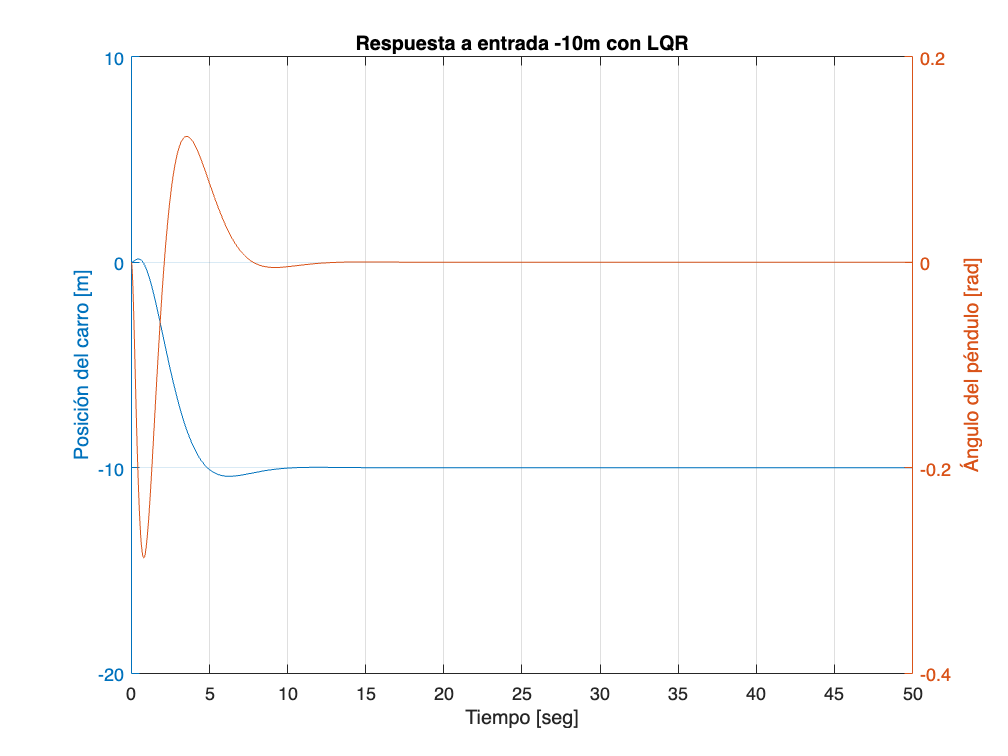

set(get(AX(1),'Ylabel'),'String','Posición del carro [m]')
set(get(AX(2),'Ylabel'),'String','Ángulo del péndulo [rad]')
title('Respuesta a entrada -10m con LQR')
xlabel('Tiempo [seg]')
grid

A continuación, el desarrollo del observador.

Se construye la matriz del observador.

Mo = obsv(olSystem)

Mo =     1.0000         0         0         0
         0         0    1.0000         0
         0    1.0000         0         0
         0         0         0    1.0000
         0   -0.0667   -0.6533         0
         0    0.0667   10.4533         0
         0    0.0044    0.0436   -0.6533
         0   -0.0044   -0.0436   10.4533


Se asignan los polos una década por debajo de la dinámica más lenta:

obsPoles = [-6 -7 -8 -9];

Se puede plantear el estimador del sistema haciendo uso de una ecuación en diferencias como la siguiente:


$$\dot{\;\hat{x} } =A\hat{\;x} +\textrm{Bu}+L\left(y-\hat{\;y} \right)$$


L se define como:

L = place(A',C',obsPoles)'

L =    14.7232    1.0119
   52.9831    6.9038
    1.0098   15.2101
    8.0392   67.5547


Se instancian entonces las matrices ampliadas:

Aamp = [(A-B*K) B*K; zeros(size(A)) (A-L*C)]

Aamp =          0    1.0000         0         0         0         0         0         0
    0.6667    1.6098   28.8151    9.1998   -0.6667   -1.6765  -29.4684   -9.1998
         0         0         0    1.0000         0         0         0         0
   -0.6667   -1.6098  -19.0151   -9.1998    0.6667    1.6765   29.4684    9.1998
         0         0         0         0  -14.7232    1.0000   -1.0119         0
         0         0         0         0  -52.9831   -0.0667   -7.5572         0
         0         0         0         0   -1.0098         0  -15.2101    1.0000
         0         0         0         0   -8.0392    0.0667  -57.1014         0


Bamp = [B; zeros(size(B))]

Bamp =          0
    0.6667
         0
   -0.6667
         0
         0
         0
         0


Camp = [Cc zeros(size(Cc))]

Camp =      1     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0


Damp = [0 0]'

Damp =      0
     0


El sistema con observador:

obsSysCL = ss(Aamp,Bamp,Camp,Damp)

obsSysCL =
 
  A = 
             x1        x2        x3        x4        x5        x6        x7        x8
   x1         0         1         0         0         0         0         0         0
   x2    0.6667      1.61     28.82       9.2   -0.6667    -1.676    -29.47      -9.2
   x3         0         0         0         1         0         0         0         0
   x4   -0.6667     -1.61    -19.02      -9.2    0.6667     1.676     29.47       9.2
   x5         0         0         0         0    -14.72         1    -1.012         0
   x6         0         0         0         0    -52.98  -0.06667    -7.557         0
   x7         0         0         0         0     -1.01         0    -15.21         1
   x8         0         0         0         0    -8.039   0.06667     -57.1         0
 
  B = 
            u1
   x1        0
   x2   0.6667
   x3        0
   x4  -0.6667
   x5        0
   x6        0
   x7        0
   x8        0
 
  C = 
       x1  x2  x3  x4  x5  x6  x7  x8
   y1   1   0  

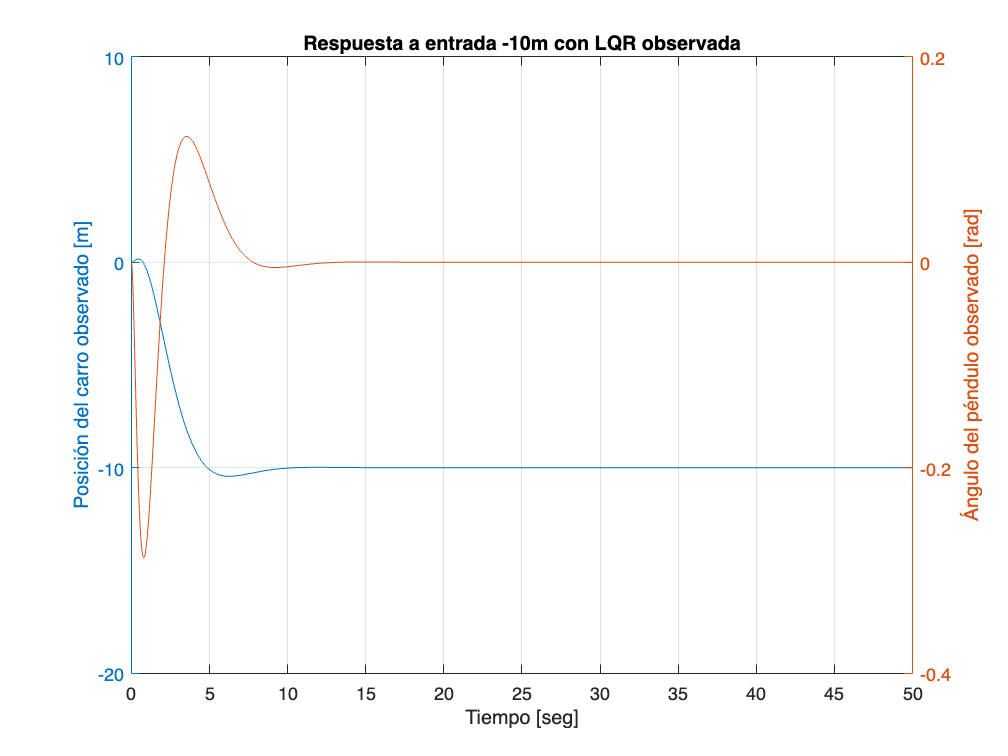

[y1,t1,x1] = lsim(obsSysCL,r,t);
[AX1,H11,H12] = plotyy(t1,y1(:,1),t1,y1(:,2),'plot');
set(get(AX1(1),'Ylabel'),'String','Posición del carro observado [m]')
set(get(AX1(2),'Ylabel'),'String','Ángulo del péndulo observado [rad]')
title('Respuesta a entrada -10m con LQR observada')
xlabel('Tiempo [seg]')
grid

Se guardan los datos en formato .mat, para poder comparar luego.

save('deltaLineal.mat','delta');
save('phiLineal.mat','phi');

### Resolución del sistema no lineal:

La resolución anterior implementa una solución al problema linealizado. Ahora se procede con la simulación no lineal del problema planteado. Se simulará haciendo uso de un bucle, como se logró hacer en el inciso anterior del motor. Al final, se compararán las respuestas de los modelos lineal y no lineal, a modo de comprender el error introducido en la linealización planteada.

m = 0.1;
F = 0.1;
l = 1;
g = 9.8;
M = 1.5;

Ahora, las matrices:

A = [0 1 0 0; 0 -F/M -m*g/M 0; 0 0 0 1; 0 F/(l*M) g*(M+m)/(l*M) 0]

A =          0    1.0000         0         0
         0   -0.0667   -0.6533         0
         0         0         0    1.0000
         0    0.0667   10.4533         0


B = [0; 1/M; 0; -1/(l*M)]

B =          0
    0.6667
         0
   -0.6667


C = [1 0 0 0]

C =      1     0     0     0


Al igual que antes:

Q = C'*C;
R = 1;
K = lqr(A,B,Q,R)

K =    -1.0000   -2.5137  -44.1772  -13.7953


Ahora, se declara G, para una referencia no nula.

G = -inv(C*inv(A-B*K)*B)

G = -1.0000

Los pasos y tiempo de simulación son los mismos que en el caso anterior:

h = 1e-4;
simTime = 50;
t = 0:h:(simTime-h);

Se pretende alcanzar una referencia de -10 metros en la evolución en el equilibrio inestable (ángulo 0).

reference = [-10 0];

Las condiciones iniciales son:

delta(1) = 0;
deltaP(1) = 0;
phi(1) = 0;
phiP(1) = 0;
stateVector = [delta(1) deltaP(1) phi(1) phiP(1)]';
xop = [0 0 0 0]';
x = [delta(1) deltaP(1) phi(1) phiP(1)]';
phiPP = 0;

La simulación:

for i = 1:(simTime/h)
    u(i) = -K*stateVector+reference(1)*G;
    delta(i) = x(1);
    deltaP(i) = x(2);
    phi(i) = x(3);
    phiP(i) = x(4);
    deltaPP = (u(i)-F*x(2)-m*l*phiPP*cos(x(3)-xop(3))+m*l*sin(x(3)-xop(3))*x(4)^2)/(M+m);
    phiPP = (g*sin(x(3)-xop(3))-deltaPP*cos(x(3)-xop(3)))/l;
    x1P = x(2);
    x2P = deltaPP;
    x3P = x(4);
    x4P = phiPP;
    xP = [x1P x2P x3P x4P]';
    x = x+xP*h;
    stateVector = [delta(i) deltaP(i) phi(i) phiP(i)]';
end

Resultados a continuación:

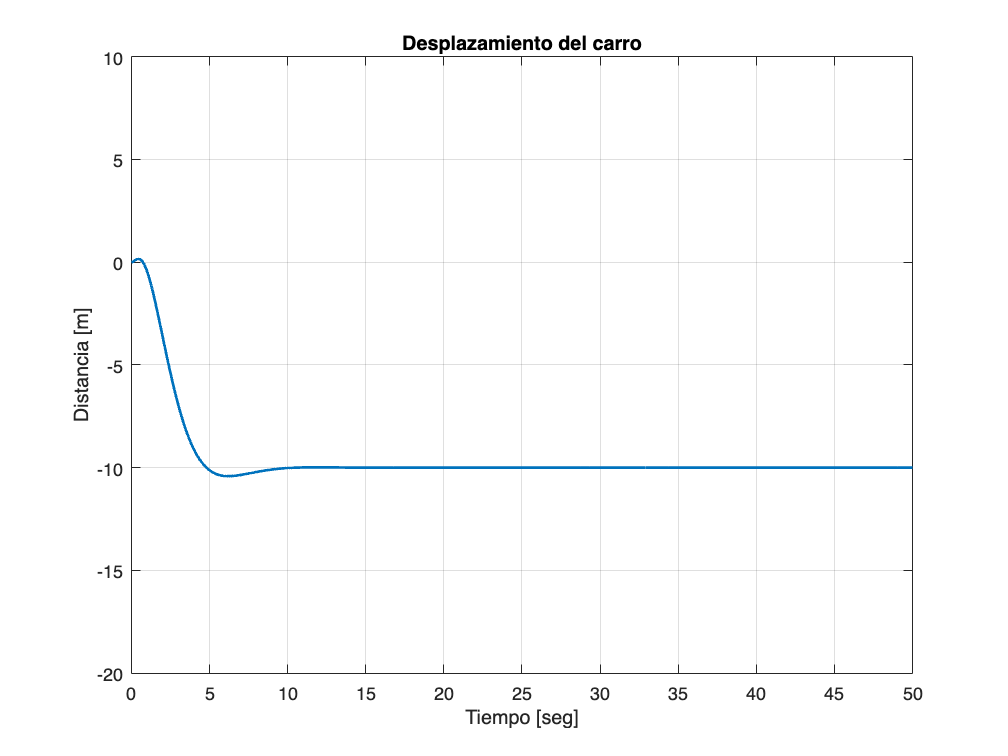

plot(t,delta,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Distancia [m]')
title('Desplazamiento del carro')
ylim([-20 10])
grid

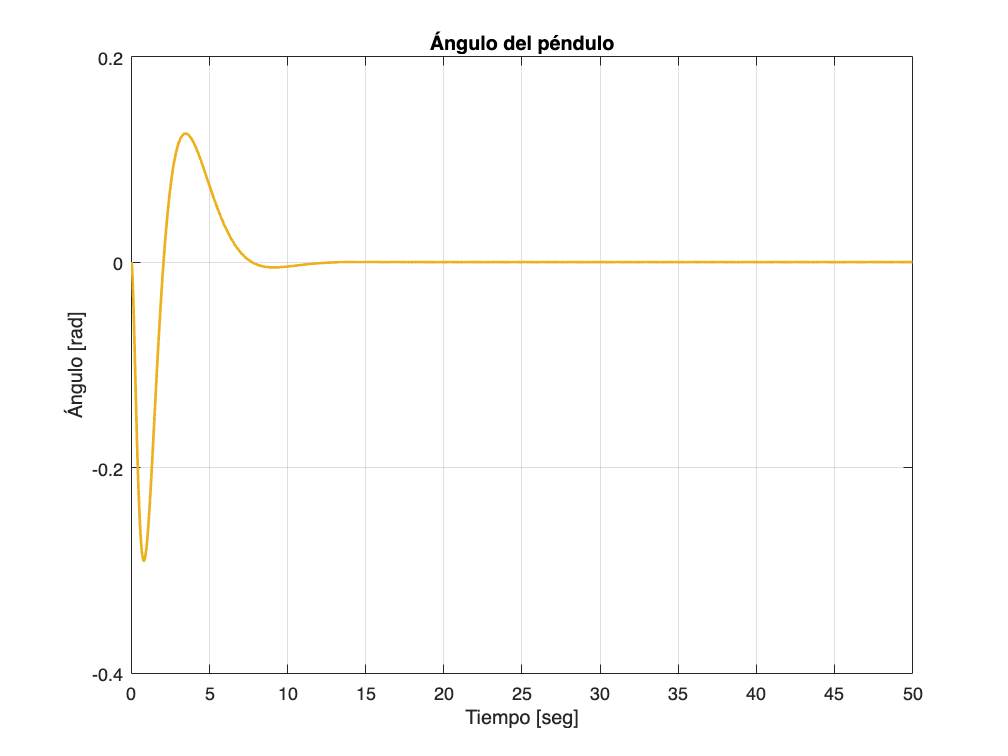

plot(t,phi,'LineWidth',1.5,'Color',[0.9290 0.6940 0.1250])
xlabel('Tiempo [seg]')
ylabel('Ángulo [rad]')
title('Ángulo del péndulo')
ylim([-0.4 0.2])
grid

save('deltaNoLineal.mat','delta');
save('phiNoLineal.mat','phi');

### Implementación del observador para el modelo no lineal

Al igual que se hizo con el motor, el procedimiento de obtención del observador se plantea de forma muy similar a la simulación del sistema no lineal, con la salvedad de que las matrices y los estados obtenidos harán referencia a las características del observador y no al sistema en sí. Por lo mencionado, es que no se describirá paso a paso el código desarrollado.

m = 0.1;
F = 0.1;
l = 1.6;
g = 9.8;
M = 1.5;
A = [0 1 0 0; 0 -F/M -m*g/M 0; 0 0 0 1; 0 F/(l*M) g*(M+m)/(l*M) 0];
B = [0; 1/M; 0; -1/(l*M)];
C = [1 0 0 0; 0 0 1 0];
Q = C'*C;
R = 1;
K = lqr(A,B,Q,R);
G = -inv(C(1,:)*inv(A-B*K)*B)

G = -1.0000

Qo = diag([1 0.01 1 0.01])

Qo =     1.0000         0         0         0
         0    0.0100         0         0
         0         0    1.0000         0
         0         0         0    0.0100


Ro = 10;
Ao = A';
Bo = C';
Ko = lqr(Ao,Bo,Qo,Ro)

Ko =     0.3983    0.1231   -0.4332   -1.1117
   -0.4332   -1.2615    5.0807   12.9505


h = 1e-4;
simTime = 50;
t = 0:h:(simTime-h);
reference = [-10 0];
delta(1) = 0;
deltaP(1) = 0;
phi(1) = 0;
phiP(1) = 0;
stateVector = [delta(1) deltaP(1) phi(1) phiP(1)]';
obsStateVector = [delta(1) deltaP(1) phi(1) phiP(1)]';
xop = [0 0 0 0]';
x = [delta(1) deltaP(1) phi(1) phiP(1)];
xObs = [0 0 0 0]';
phiPP = 0;
for i = 1:(simTime/h)
    u(i) = -K*stateVector+reference(1)*G;
    delta(i) = x(1);
    deltaP(i) = x(2);
    phi(i) = x(3);
    phiP(i) = x(4);
    deltaPP = (u(i)-F*x(2)-m*l*phiPP*cos(x(3)-xop(3))+m*l*sin(x(3)-xop(3))*x(4)^2)/(M+m);
    phiPP = (g*sin(x(3)-xop(3))-deltaPP*cos(x(3)-xop(3)))/l;
    x1P = x(2);
    x2P = deltaPP;
    x3P = x(4);
    x4P = phiPP;
    xP = [x1P x2P x3P x4P]';
    x = x+xP*h;
    deltaO(i) = xObs(1);
    deltaPO(i) = xObs(2);
    phiO(i) = xObs(3);
    phiPO(i) = xObs(4);
    yO = C*obsStateVector;
    y = C*stateVector;
    error = y-yO;
    xPrevP = A*xObs+B*u(i)+Ko'*error;
    xObs = xObs + xPrevP*h;
    stateVector = [delta(i) deltaP(i) phi(i) phiP(i)]';
    obsStateVector = [deltaO(i) deltaPO(i) phiO(i) phiPO(i)]';
end

Se muestran las gráficas de ángulo y de posición observadas.

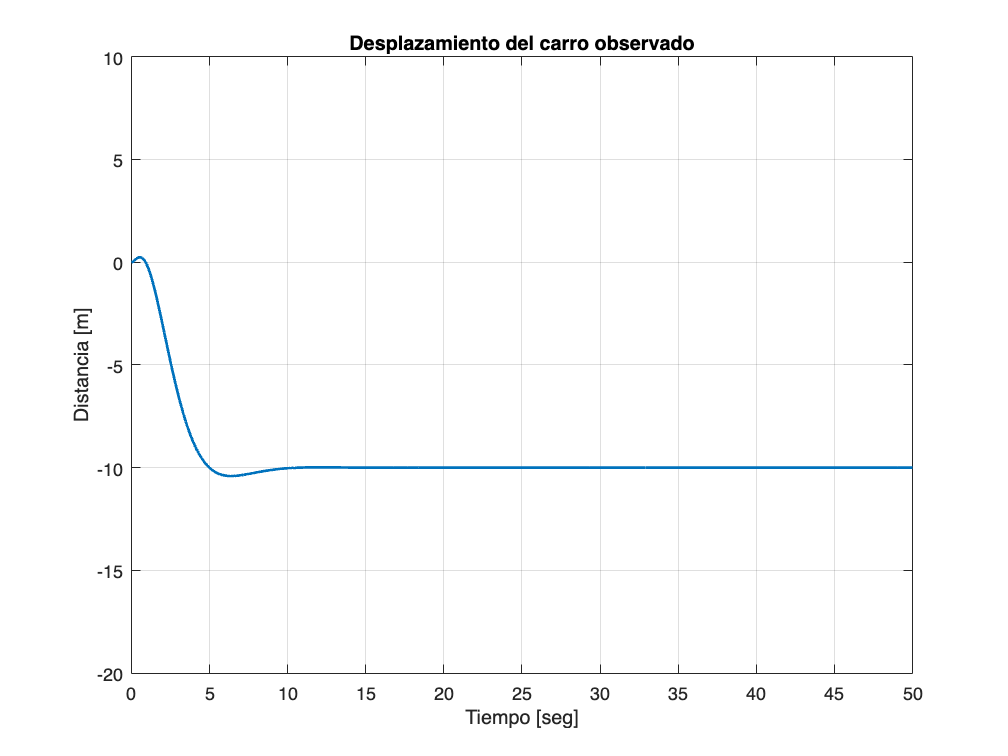

plot(t,deltaO,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Distancia [m]')
title('Desplazamiento del carro observado')
ylim([-20 10])
grid

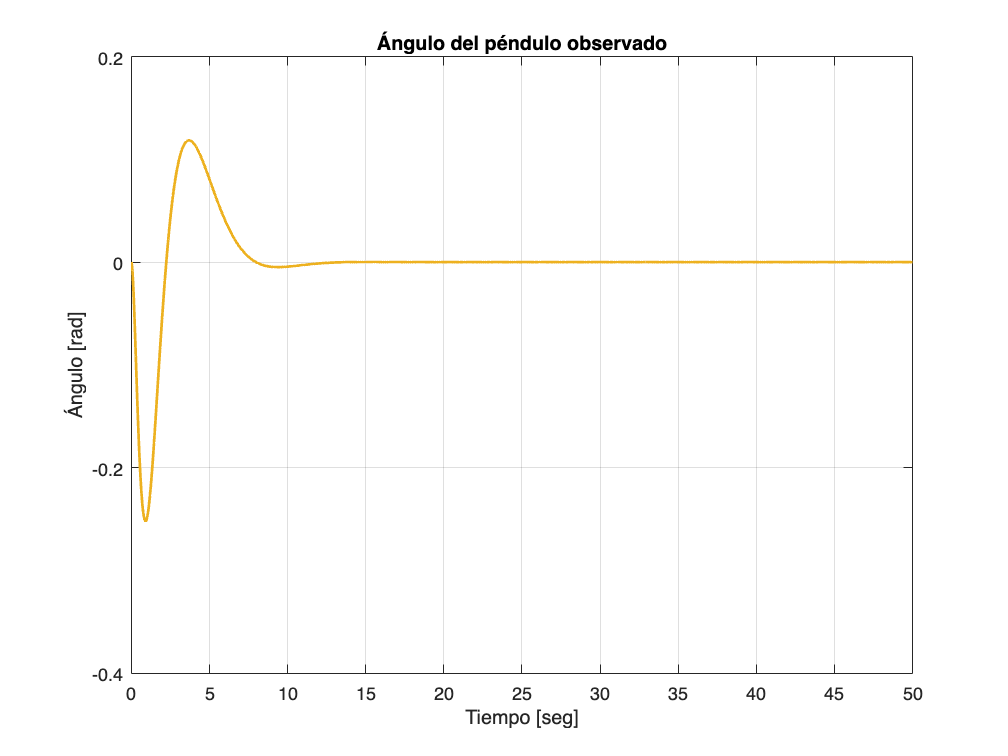

plot(t,phiO,'LineWidth',1.5,'Color',[0.9290 0.6940 0.1250])
xlabel('Tiempo [seg]')
ylabel('Ángulo [rad]')
title('Ángulo del péndulo observado')
ylim([-0.4 0.2])
grid

Se compara con lo obtenido de forma real:

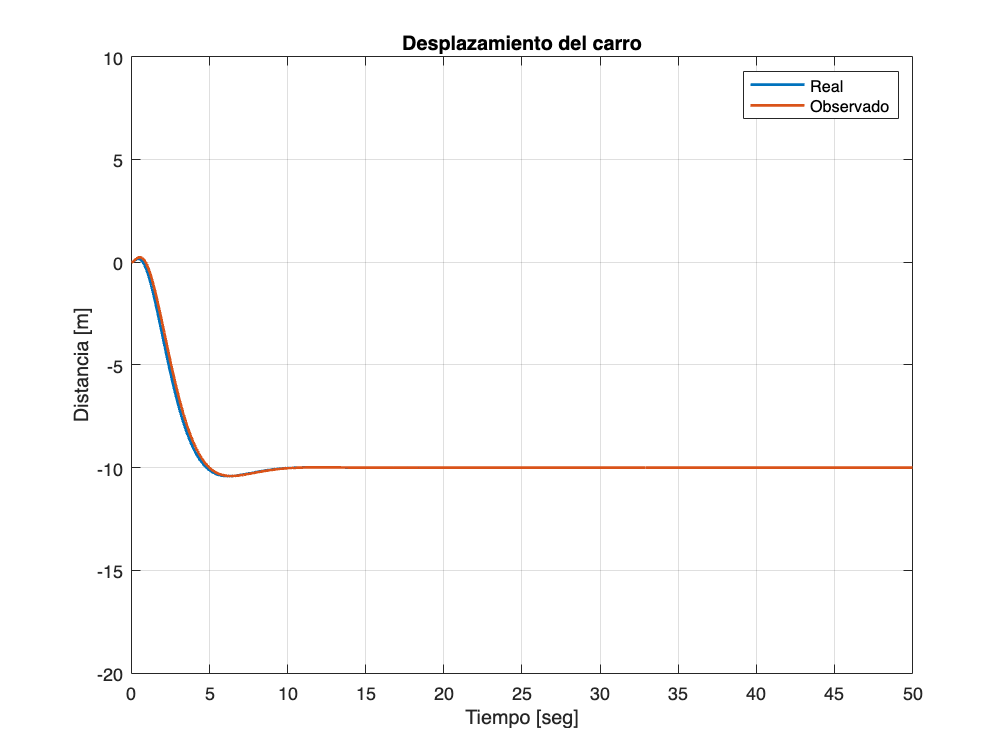

deltaReal = load('deltaNoLineal.mat');
phiReal = load('phiNoLineal.mat');
plot(t,deltaReal.delta,'LineWidth',1.5)
hold on
plot(t,deltaO,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Distancia [m]')
title('Desplazamiento del carro')
ylim([-20 10])
legend('Real','Observado')
grid
hold off

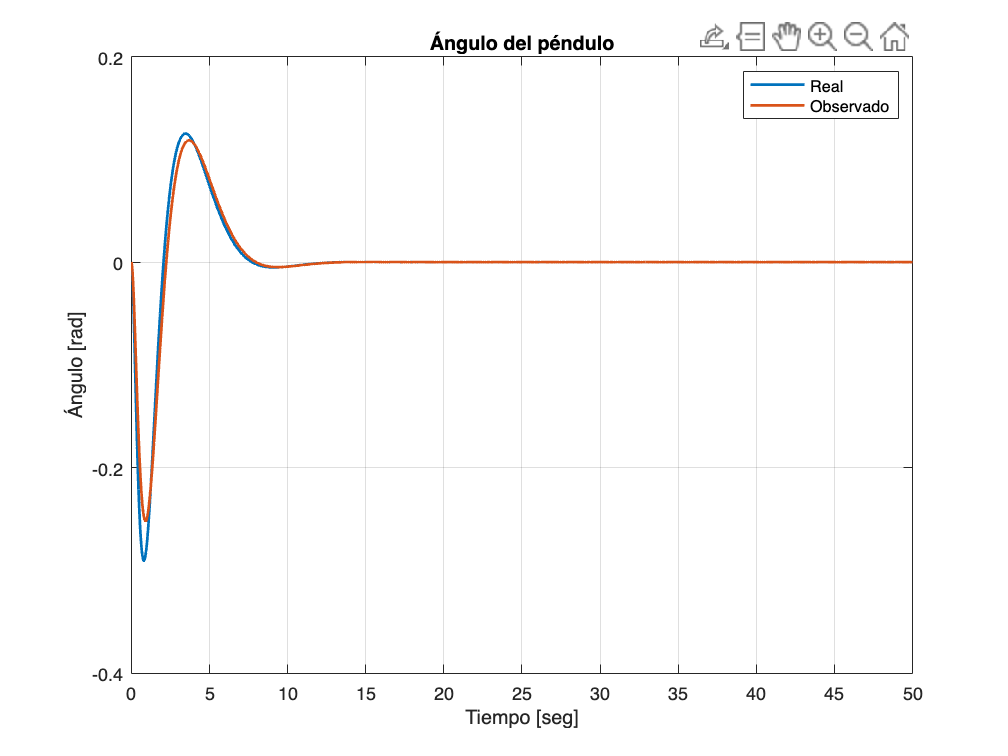

plot(t,phiReal.phi,'LineWidth',1.5)
hold on
plot(t,phiO,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Ángulo [rad]')
title('Ángulo del péndulo')
ylim([-0.4 0.2])
legend('Real','Observado')
grid
hold off

### Controlador con variación de parámetros

Los incisos 5 y 6 de la consigna son análogos a los últimos 2, en donde se tiene un sistema a plantear y luego se plantea la observación de la evolución. De modo de ahorrar código, se plantearán ambas consignas en el mismo código, para que al finalizar se cuente de una única vez con las variables necesarias.

Para esta simulación es necesario plantear la situación en que una grúa toma una carga, por lo que en un inicio la masa del carro es determinada, pero luego, ésta aumenta. Primero se plantea el caso de la carga inicial, que tiene los mismos datos que los anteriormente planteados.

m = 0.1;
F = 0.1;
l = 1.6;
g = 9.8;
M = 1.5;

Las matrices linealizadas, al igual que antes, son:

A = [0 1 0 0; 0 -F/M -m*g/M 0; 0 0 0 1; 0 -F/(l*M) -g*(M+m)/(l*M) 0]

A =          0    1.0000         0         0
         0   -0.0667   -0.6533         0
         0         0         0    1.0000
         0   -0.0417   -6.5333         0


B = [0; 1/M; 0; 1/(l*M)]

B =          0
    0.6667
         0
    0.4167


C = [1 0 0 0]

C =      1     0     0     0


Para controlar el sistema, se amplían las matrices:

Aamp = [A zeros(4,1); -C 0]

Aamp =          0    1.0000         0         0         0
         0   -0.0667   -0.6533         0         0
         0         0         0    1.0000         0
         0   -0.0417   -6.5333         0         0
   -1.0000         0         0         0         0


Bamp = [B; 0]

Bamp =          0
    0.6667
         0
    0.4167
         0


Camp = [C 0]

Camp =      1     0     0     0     0


Para el uso del LQR.

Q = diag([1 10 10000 100 10])

Q =            1           0           0           0           0
           0          10           0           0           0
           0           0       10000           0           0
           0           0           0         100           0
           0           0           0           0          10


R = 100;
K = lqr(Aamp,Bamp,Q,R)

K =     1.2232    2.2498    6.7212    2.7929   -0.3162


El integrador se plantea a continuación:

Kint = K(1:4)

Kint =     1.2232    2.2498    6.7212    2.7929


Kint1 = -K(5)

Kint1 = 0.3162

La carga se plantea como:

m1 = 10*m;
Acar = [0 1 0 0; 0 -F/M -m1*g/M 0; 0 0 0 1; 0 -F/(l*M) -g*(M+m1)/(l*M) 0]

Acar =          0    1.0000         0         0
         0   -0.0667   -6.5333         0
         0         0         0    1.0000
         0   -0.0417  -10.2083         0


Bcar = [0; 1/M; 0; 1/(l*M)]

Bcar =          0
    0.6667
         0
    0.4167


Ccar = [1 0 0 0];
AampC = [Acar zeros(4,1); -Ccar 0]

AampC =          0    1.0000         0         0         0
         0   -0.0667   -6.5333         0         0
         0         0         0    1.0000         0
         0   -0.0417  -10.2083         0         0
   -1.0000         0         0         0         0


BampC = [Bcar; 0]

BampC =          0
    0.6667
         0
    0.4167
         0


CampC = [Ccar 0]

CampC =      1     0     0     0     0


Qcar = diag([1 1000 1 100000 1])

Qcar =            1           0           0           0           0
           0        1000           0           0           0
           0           0           1           0           0
           0           0           0      100000           0
           0           0           0           0           1


Rcar = 100;
Kcar = lqr(AampC,BampC,Qcar,Rcar)

Kcar =     0.9550    4.4103   31.3625   27.1855   -0.1000


KintCar = Kcar(1:4)

KintCar =     0.9550    4.4103   31.3625   27.1855


KintCar1 = -Kcar(5)

KintCar1 = 0.1000

Ahora, se deben plantear dos observadores también, uno para cada caso de carga:

A1 = [0 1 0 0; 0 -F/M -m*g/M 0; 0 0 0 1; 0 -F/(l*M) -g*(M+m)/(l*M) 0];
B1 = [0; 1/M; 0; 1/(l*M)];
C1 = [1 0 0 0; 0 0 1 0];
Ao = A1';
Bo = C1';
A2 = [0 1 0 0; 0 -F/M -m1*g/M 0; 0 0 0 1; 0 -F/(l*M) -g*(M+m1)/(l*M) 0];
B2 = [0; 1/M; 0; 1/(l*M)];
C2 = [1 0 0 0; 0 0 1 0];
AoCar = A2';
BoCar = C2';

Para diseñar la matriz K del observador para el caso sin carga, se colocan polos décadas por debajo de lo obtenido con los cálculos.

Kob = place(Ao,Bo,[-200 -300 -400 -500])

Kob = 1.0e+05 *

    0.0069    1.1158    0.0009    0.3251
    0.0010    0.3717    0.0071    1.1833


Para la matriz K del segundo controlador se utiliza la función LQR.

QoCar = diag([1 0.1 1 1])

QoCar =     1.0000         0         0         0
         0    0.1000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


RoCar = 1;
KoCar = lqr(AoCar,BoCar,QoCar,RoCar)

KoCar =     1.9137    1.3970    0.3632    1.2106
    0.3632   -0.1964    0.8791   -0.0477


La referencia es variable para este caso de simulación. Se deben alcanzar 2 metros, aumentar la masa del carro en 10 veces, y luego se debe volver al origen, es decir, una posición de cero. Se simularán 100 segundos, que sería el doble de tiempo de las simulaciones anteriores, para poder plantear un caso de ida y vuelta. La referencia, al igual que ocurría con el caso del motor se declara mediante el uso de la función square de Matlab.

h = 1e-4;
simTime = 100;
t = 0:h:(simTime-h);
refDelta = square(2*pi*(1/100)*t)+1;
reference = [refDelta pi];

Como se tiene una masa variable:

mass = -0.45*square(2*pi*(1/100)*t)+0.55;

Las condiciones iniciales son:

delta(1) = 0;
deltaP(1) = 0;
phi(1) = pi;
phiP(1) = 0;
stateVector = [delta(1) deltaP(1) phi(1) phiP(1)]';
xop = [0 0 pi 0]';
x = [delta(1) deltaP(1) phi(1) phiP(1)]';
zeta(1) = 0;
integ(1) = zeta(1);
phiPP = 0;

A continuación la simulación real (sin el observador):

K = Kint;
KI = Kint1;
for i = 1:(simTime/h)
    if(mass(i) > 0.1)
        K = KintCar;
        KI = KintCar1;
    end
    zetaP = refDelta(i)-C1(1,:)*(stateVector-xop);
    zeta(i) = integ+h*zetaP;
    u(i) = -K*(stateVector(1:4)-xop(1:4))+KI*zeta(i);
    delta(i) = x(1);
    deltaP(i) = x(2);
    phi(i) = x(3);
    phiP(i) = x(4);
    deltaPP = (u(i)-F*x(2)-mass(i)*l*phiPP*cos(x(3))+mass(i)*l*sin(x(3))*x(4)^2)/(M+mass(i));
    phiPP = (g*sin(x(3))-deltaPP*cos(x(3)))/l;
    x1P = x(2);
    x2P = deltaPP;
    x3P = x(4);
    x4P = phiPP;
    xP = [x1P x2P x3P x4P]';
    x = x+xP*h;
    stateVector = [delta(i) deltaP(i) phi(i) phiP(i)]';
    integ = zeta(i);
end

Se muestran a continuación los resultados de simular:

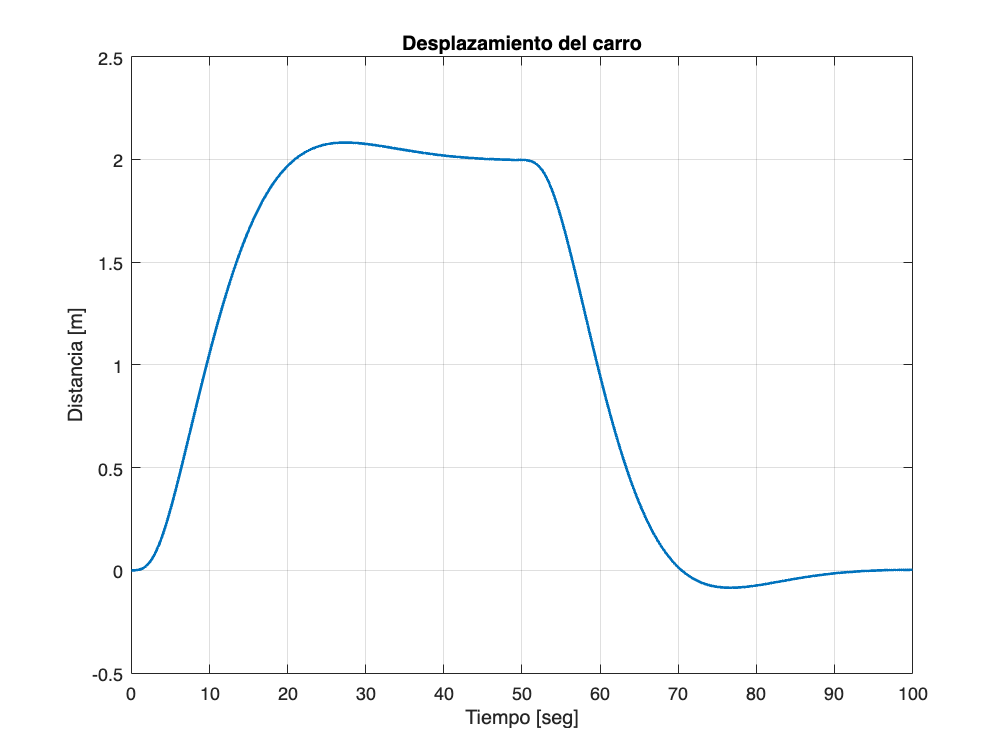

plot(t,delta,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Distancia [m]')
title('Desplazamiento del carro')
grid

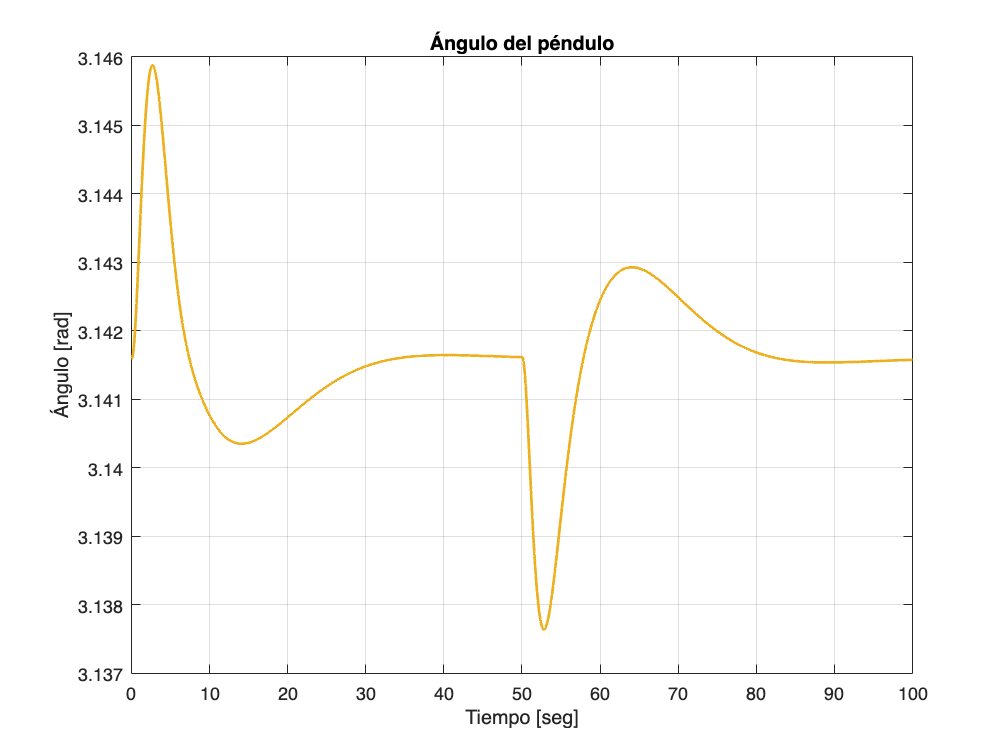

delt = delta;
ph = phi;
plot(t,phi,'LineWidth',1.5,'Color',[0.9290 0.6940 0.1250])
xlabel('Tiempo [seg]')
ylabel('Ángulo [rad]')
title('Ángulo del péndulo')
grid

Ahora, para el observador:

clear delta; clear deltaP; clear phi; clear phiP; 
clear stateVector; clear xop; clear x; clear phiPP; 
clear deltaPP; clear x1P; clear x2P;
clear x3P; clear x4P;
deltaO(1) = 0;
deltaPO(1) = 0;
phiO(1) = pi;
phiPO(1) = 0;
states = [deltaO(1) deltaPO(1) phiO(1) phiPO(1)]';
xop = [0 0 pi 0]';
x = [deltaO(1) deltaPO(1) phiO(1) phiPO(1)]';
zetaObs(1) = 0;
integObs(1) = zetaObs(1);
phiPP = 0;
xObs = [deltaO(1) deltaPO(1) phiO(1) phiPO(1)]';
obsStateVector = [deltaO(1) deltaPO(1) phiO(1) phiPO(1)]';
K = Kint;
KI = Kint1;
Ko = Kob;
for i = 1:(simTime/h)
    if(mass(i) > 0.1)
        K = KintCar;
        KI = KintCar1;
        Ko = KoCar;
    end
    zetaPObs = refDelta(i)-C1(1,:)*(obsStateVector-xop);
    zetaObs(i) = integObs+h*zetaPObs;
    u(i) = -K*(obsStateVector-xop)+KI*zetaObs(i);
    deltaO(i) = x(1);
    deltaPO(i) = x(2);
    phiO(i) = x(3);
    phiPO(i) = x(4);
    deltaPP = (u(i)-F*x(2)-mass(i)*l*phiPP*cos(x(3))+mass(i)*l*sin(x(3))*x(4)^2)/(M+mass(i));
    phiPP = (g*sin(x(3))-deltaPP*cos(x(3)))/l;
    x1P = x(2);
    x2P = deltaPP;
    x3P = x(4);
    x4P = phiPP;
    xP = [x1P x2P x3P x4P]';
    x = x+xP*h;
    deltaObs(i) = xObs(1);
    deltaPObs(i) = xObs(2);
    phiObs(i) = xObs(3);
    phiPObs(i) = xObs(4);
    yObs = C1*obsStateVector;
    y = C1*states;
    error = y-yObs;
    xPrevP = A*(xObs-xop)+B*u(i)+Ko'*error;
    xObs = xObs+h*xPrevP;
    states = [deltaO(i) deltaPO(i) phiO(i) phiPO(i)]';
    obsStateVector = [deltaObs(i) deltaPObs(i) phiObs(i) phiPObs(i)]';
    integObs = zetaObs(i);
end

A continuación los resultados del observador:

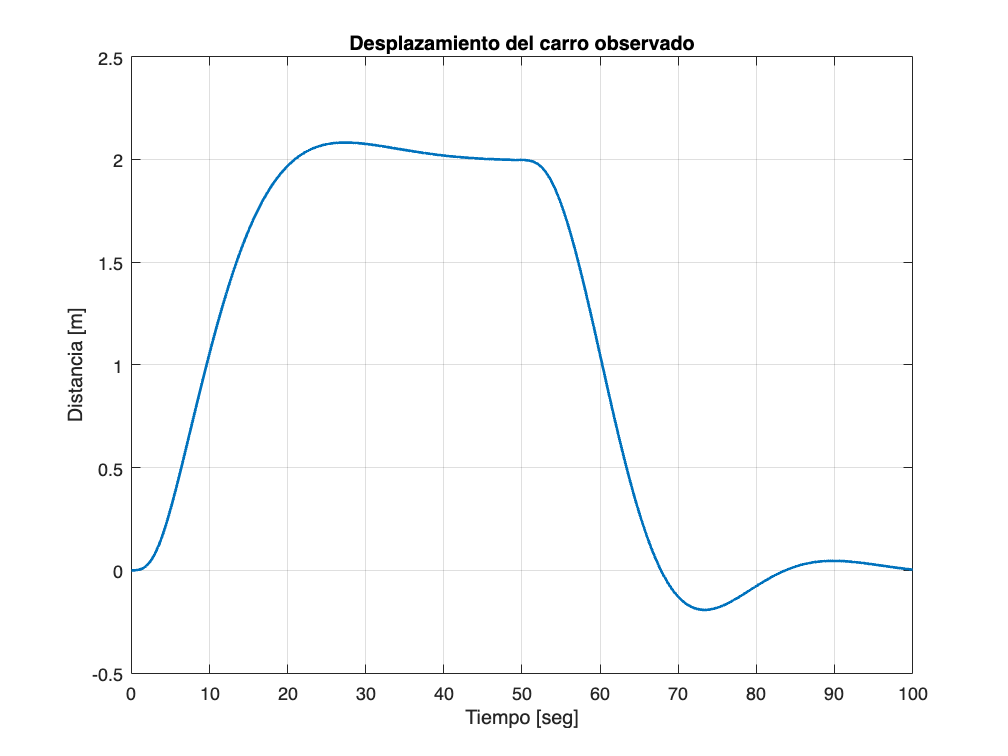

plot(t,deltaO,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Distancia [m]')
title('Desplazamiento del carro observado')
grid

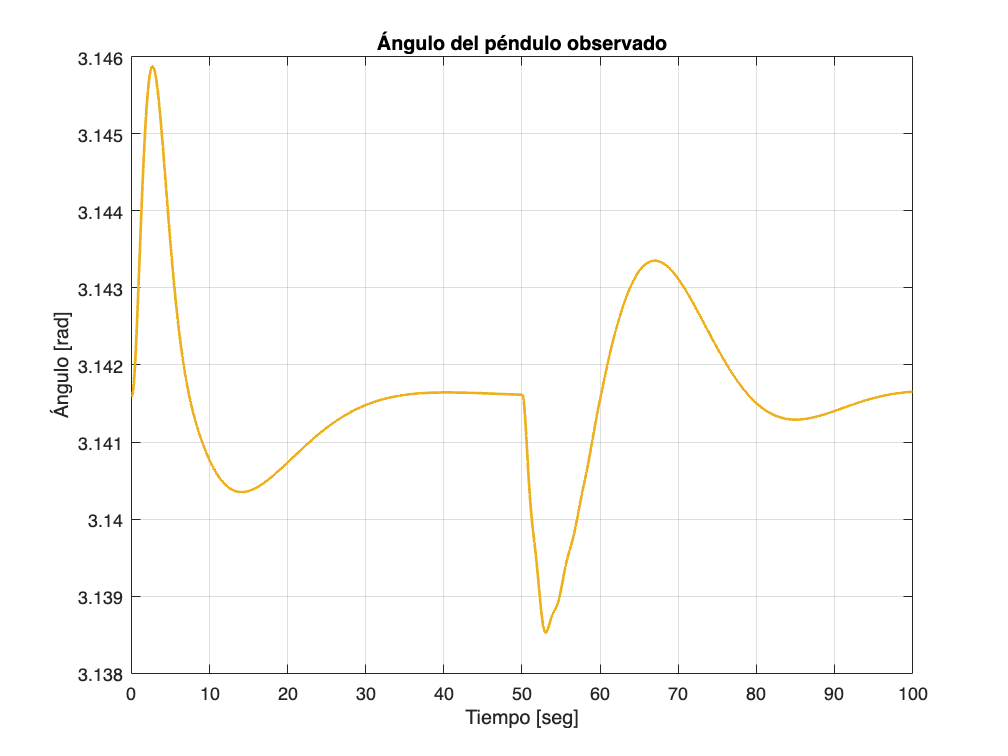

plot(t,phiO,'LineWidth',1.5,'Color',[0.9290 0.6940 0.1250])
xlabel('Tiempo [seg]')
ylabel('Ángulo [rad]')
title('Ángulo del péndulo observado')
grid

A continuación se comparan las gráficas reales y las observadas:

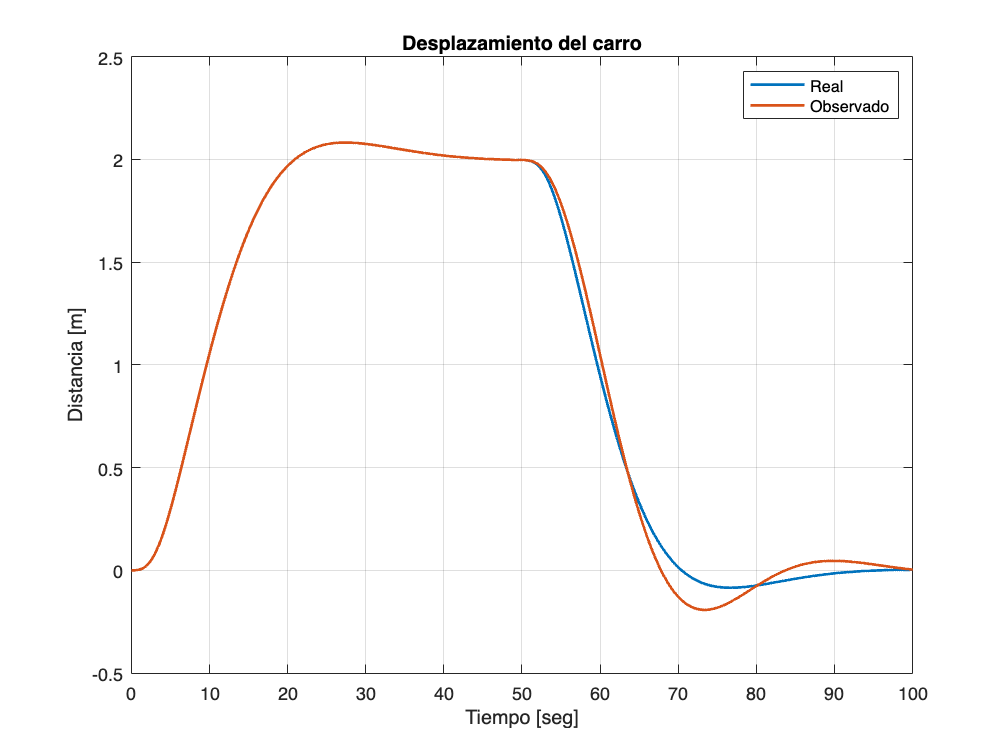

plot(t,delt,'LineWidth',1.5)
hold on
plot(t,deltaO,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Distancia [m]')
title('Desplazamiento del carro')
legend('Real','Observado')
grid
hold off

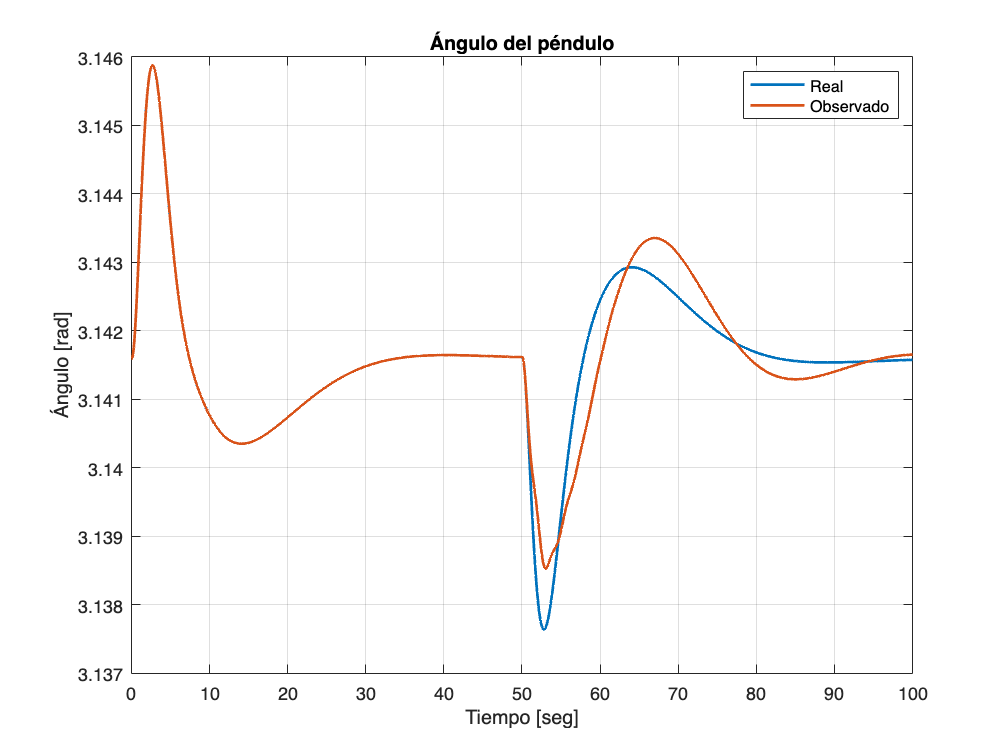

plot(t,ph,'LineWidth',1.5)
hold on
plot(t,phiO,'LineWidth',1.5)
xlabel('Tiempo [seg]')
ylabel('Ángulo [rad]')
title('Ángulo del péndulo')
legend('Real','Observado')
grid
hold off